# Kondition einer Basis

Die schlechte Kondition der monomialen Basis $1$, $t$, $t^2$, $\ldots$ des Polynomraums wird veranschaulicht: kleine Störungen in den Koeffizienten können große Änderungen in den entsprechenden Polynomen bewirken. 

Als Beispiel betrachten wir  das Polynom $p(t)=\sum_{i=0}^{m} a_i\, t^{i}$, mit Koeffizienten $a_i=(i+1)^{-4}$, $i=0,\ldots,m,$ auf einem Intervall $[0,b]$, $b>0$. 

Wir wählen (leicht) geänderte  Koeffizienten $\tilde a_i=a_i+\delta\, z_i$, wobei  die Komponenten $z_i$ des Störungsvektors $z \in R^{m+1}$ Realisierungen einer standard normalverteilten Zufallsvariable sind.

Der Vektor $z$ wird so skaliert, dass $\|z\|_\infty=1$ gilt. 

Mit diesem Programm: 

- können Experimente mit den Parameterwerten $m$ (Grad des Polynoms), $b$ (Länge des Intervalls) und $\delta$ (Größe der Störung) durchgeführt werden

- Effekte, die durch die Parameteränderung hervorgerufen werden, beobachtet werden.

Parameterwerte für den Grad $m$  und  Länge des Intervalls $b$:

m=3;
Polynomgrad=m

Polynomgrad = 3

b=3

b = 3

Der Parameter $\delta$bestimmt die Größe der (absoluten) Störung:

delta=0.01

delta = 0.0100

Im folgenden werden die Polynome $p(t)$ und $\tilde p(t)= \sum_{i=0}^{m} \tilde a_i\, t^{i}$ für $t \in[0,b]$ gezeigt. 

z =     0.3371
    0.6291
    1.0000
    0.0254


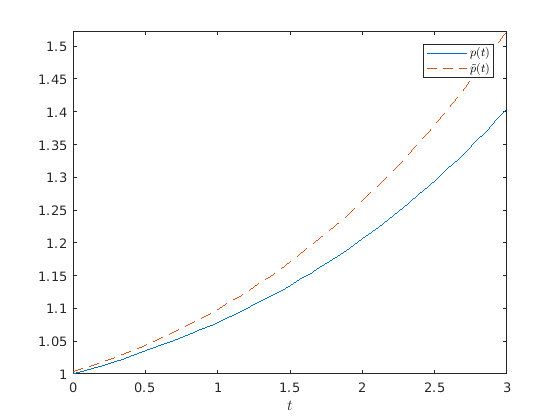

plotit(m,b,delta);

# Aktivität:

Variieren Sie $m$, $b$ und $\delta$ und schließen Sie, dass aus kleinen Änderungen der Koeffizienten  (sehr) große Änderungen des entsprechenden Polynoms resultieren können. 

function plotit(m,b,delta)
    global a;
    global z;
        z = randn(m+1,1);
        z=z/norm(z,inf)       
    close all;
    hold off;
    a=ones(m+1,1);
    for i=0:m
        a(i+1)=1/(i+1)^4;
    end
    fplot(@(t) polyexact(t,a,m),[0 b]);
    hold on;        
    deltaz=delta*z;
    fplot(@(t) polyexact(t,a+deltaz,m),[0 b],'--');
    leg1=legend('$p(t)$','$\tilde p(t)$');
    set(leg1,'Interpreter','latex');
    xlabel('$t$','Interpreter','latex');
end

function y=polyexact(t,a,m)
    n=length(t);
    T=zeros(m+1,n);
    for i=1:m+1
         T(i,:)=t.^(i-1);
    end
    y=a'*T;    
end

